# Ejercicio 2.2: Modelo de convección atmosférica de Lorenz

**a)**

[s, b, r] = deal(10, 8/3, 28); %Soluciones caóticas

x0 = [1; 1; 1];
tspan = [0, 60];

[t, x] = ode45(@(t, x)lorenz(t, x, s, b, r), tspan, x0)

t =          0
    0.0019
    0.0039
    0.0058
    0.0077
    0.0174
    0.0271
    0.0367
    0.0464
    0.0582


x =     1.0000    1.0000    1.0000
    1.0005    1.0502    0.9968
    1.0019    1.1004    0.9938
    1.0043    1.1505    0.9909
    1.0076    1.2008    0.9880
    1.0371    1.4545    0.9758
    1.0876    1.7162    0.9671
    1.1583    1.9911    0.9623
    1.2487    2.2843    0.9624
    1.3855    2.6743    0.9705


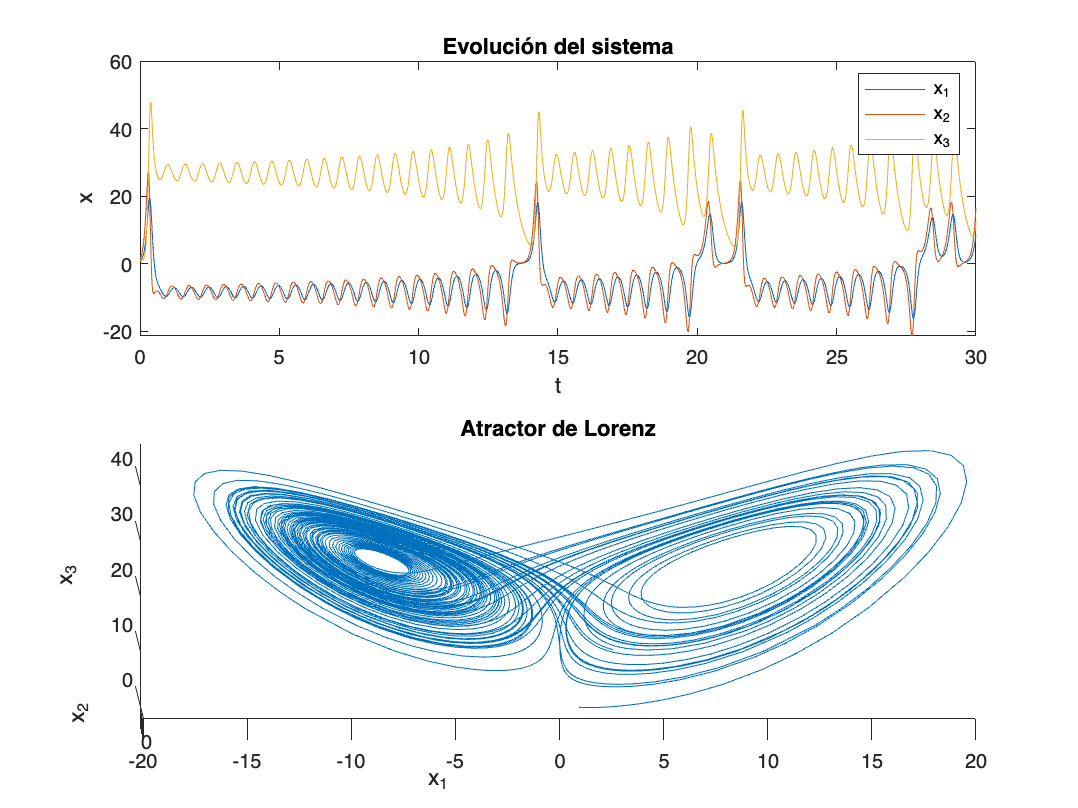


figure(1);
subplot(2, 1, 1)
plot(t, x)
title("Evolución del sistema")
legend("x_1", "x_2", "x_3")
ylabel("x")
xlabel("t")
xlim([0, 30])

subplot(2,1,2)
plot3(x(:,1), x(:,2), x(:,3));
title("Atractor de Lorenz")
xlabel("x_1")
ylabel("x_2")
zlabel("x_3")

**b)**

%Compruebo que converge para rho < 1

r = 0.9

r = 0.9000

[t, x] = ode45(@(t, x)lorenz(t, x, s, b, r), tspan, x0)

t =          0
    0.0301
    0.0603
    0.0904
    0.1206
    0.1486
    0.1766
    0.2046
    0.2326
    0.2681


x =     1.0000    1.0000    1.0000
    0.9959    0.9681    0.9512
    0.9848    0.9385    0.9050
    0.9687    0.9111    0.8613
    0.9499    0.8858    0.8198
    0.9315    0.8639    0.7830
    0.9124    0.8435    0.7479
    0.8930    0.8244    0.7144
    0.8739    0.8065    0.6824
    0.8505    0.7855    0.6440


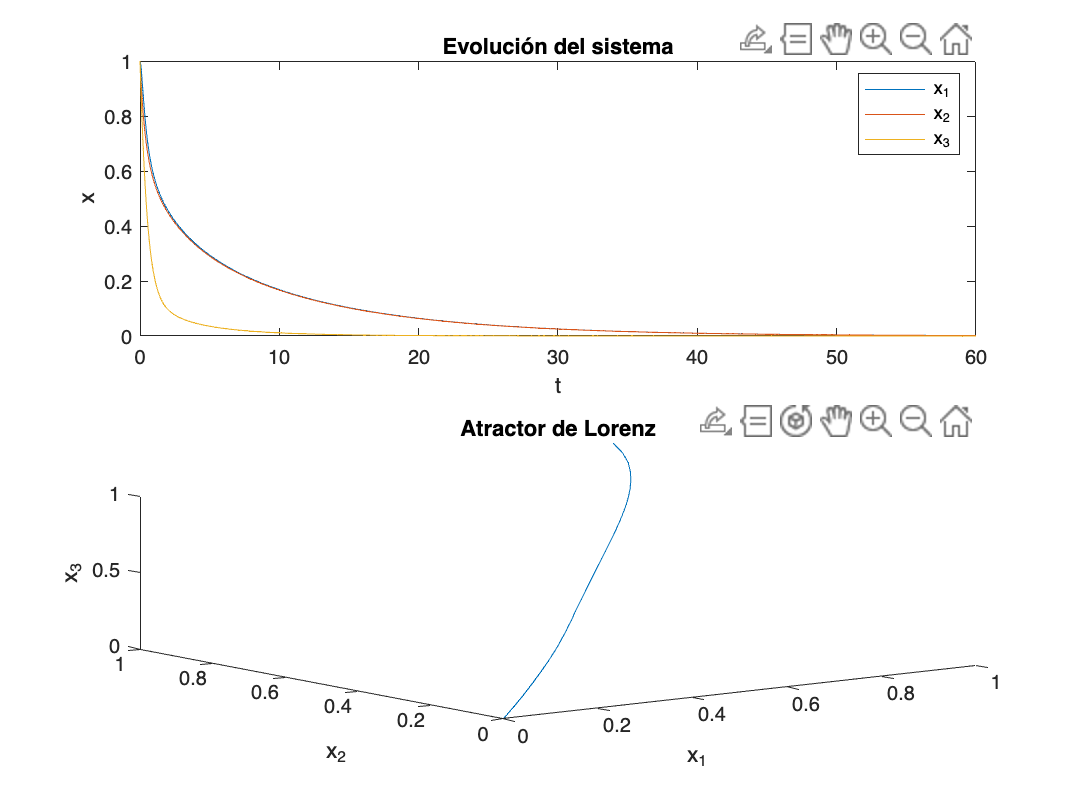


figure(2);
subplot(2, 1, 1)
plot(t, x)
title("Evolución del sistema")
legend("x_1", "x_2", "x_3")
ylabel("x")
xlabel("t")

subplot(2,1,2)
plot3(x(:,1), x(:,2), x(:,3));
title("Atractor de Lorenz")
xlabel("x_1")
ylabel("x_2")
zlabel("x_3")


%El punto de equilibrio es (0,0,0). Se puede comprobar que el sistema
%converge al origen tanto en la gráfica de fases como en la evolución temporal individual de cada componente. 

Los puntos de equilibrio siguen las ecuaciones


$$0 = \sigma x_1 - \sigma x_2 \Rightarrow x_1  = x_2 \\

0 = x_1 (\rho - x_3) - x_2 \Rightarrow x_1(\rho - 1 - x_3) = 0\\

0 = x_1x_2 - \beta x_3 \Rightarrow x_1 = \pm \sqrt{\beta x_3}$$


Ahora bien, si rho es menor que uno, solo valdrá la solución 


$$x_1 = x_2 = x_3 = 0$$


pero si es mayor, las soluciones serán


$$x_1 = x_2 = x_3 = 0$$


y


$$x_3 = \rho - 1 \\
x_1 = x_2 = \pm \sqrt{\beta(\rho - 1)}$$


Nótese que para este cálculo se ha considerado que beta es positivo (en concreto, en el enunciado este parámetro es igual a 8/3). En el caso de que rho sea igual a 1 ambas soluciones son equivalentes y devuelven el origen. Por tanto, rho = 1 es el punto en el que el sistema pasa de tener un punto de equilibrio (0, 0, 0) a tener 3:$(0, 0, 0), (\sqrt{\beta(\rho - 1)}\mbox{, }\sqrt{\beta(\rho - 1)}, \rho - 1) \mbox{ y }  (-\sqrt{\beta(\rho - 1)}, -\sqrt{\beta(\rho - 1)}, \rho - 1)$.

De modo que el sistema tiene una bifurcación *pitchfork* en rho = 1. 

function xdot = lorenz(t, x, s, b, r)

    xdot(1,1) = s*(x(2,1) - x(1,1));
    xdot(2,1) = x(1,1) * (r - x(3,1)) - x(2,1);
    xdot(3,1) = x(1,1) * x(2,1) - b * x(3,1);
end